R = 100;
C = 10e-6;

zeta = 0.1;
L = R^2*C/(4*zeta^2) 

L = 2.5000

s = tf('s');
T = 1/(L*C*s^2+R*C*s+1)

T =
 
              1
  -------------------------
  2.5e-05 s^2 + 0.001 s + 1
 
Continuous-time transfer function.



[p,z] = pzmap(T)

p = 	1.0e+02 *

  -0.2000 + 1.9900i
  -0.2000 - 1.9900i



z =

  0×1 empty double column vector



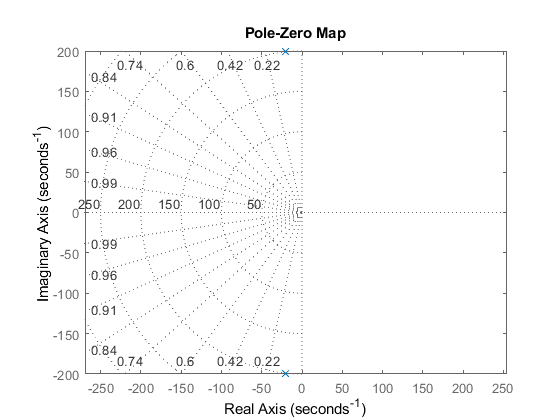

pzmap(T)
axis equal
grid on

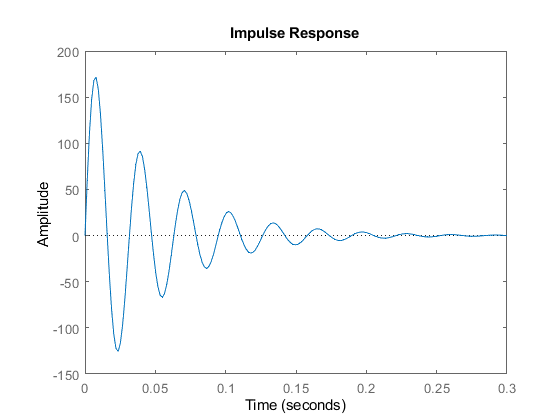

impulse(T)

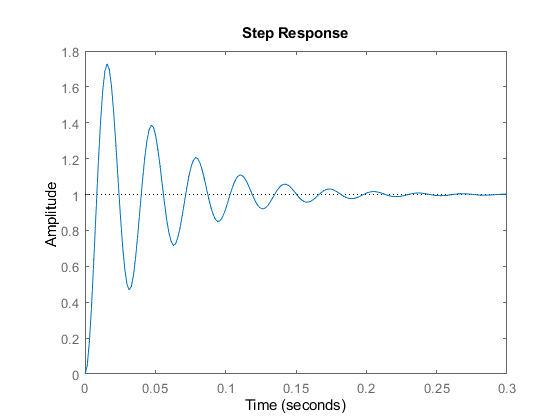

step(T)

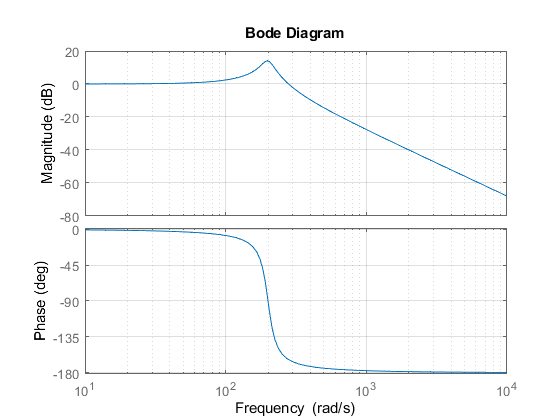

bode(T)
grid on

w = 1/sqrt(L*C)

w = 200

[mag,phase] = bode(T,w/10)

mag = 1.0099

phase = -1.1573

[mag,phase] = bode(T,w)

mag = 5.0000

phase = -90.0000

[mag,phase] = bode(T,w*10)

mag = 0.0101

phase = -178.8427

wd = (1-zeta^2)*w;
[mag,phase] = bode(T,wd)

mag = 5.0252

phase = -84.2608